# [使用虚幻引擎的交通信号灯协商](https://ww2.mathworks.cn/help/driving/ug/traffic-light-negotiation-with-unreal-engine-visualization.html)

该研究展示了在[虚幻引擎驾驶仿真环境](http://c/matlab_2022a/toolbox/shared/sim3d_projects/automotive_project/UE4/WindowsNoEditor/AutoVrtlEnv/Binaries/Win64)中如何设计和和仿真车辆进行交通灯的协商（[视频教程](https://www.bilibili.com/video/BV19i4y177Hg/)）。

## 介绍

用于协商交通信号灯的决策逻辑是自动驾驶应用程序的基本组成部分。决策逻辑与控制器交互，根据红绿灯和自我车道中其他车辆的状态来驾驶自我车辆（拥有自我意识的车辆、自动驾驶汽车）。使用真实条件模拟真实世界的交通场景可以更深入地了解决策逻辑和控制器之间的交互。 自动驾驶工具箱™ 提供由 Epic Games® 的 虚幻引擎® 提供支持的 3D 模拟环境。 您可以使用此引擎在预建的 3D 场景中可视化车辆的运动。该引擎提供了一种直观的方式来分析决策逻辑和控制算法在十字路口通过红绿灯时的性能。

有关如何设计决策逻辑和控件以在长方体环境中协商交通灯的信息，请参阅[交通灯协商](docid:driving_ug#mw_1dfb179e-833f-46da-9109-2e6d246b4609)示例。 此示例展示了如何在虚幻场景中控制交通灯，以及如何针对不同的测试场景模拟和可视化车辆行为。 在本研究中，您将：

- **探索测试基准模型的架构：**模型包含传感器和环境、（路径是预先定义好的）、交通灯决策逻辑、控制、车辆动力学。

- **在一个仿真场景中控制信号灯：**`Simulation` `3D` `Traffic` `Light` `Controller` 帮助模块通过使用 Simulink® 在虚幻场景中配置模型来控制交通灯的状态。

- **仿真由绿变红时车辆的行为：**该模型分析了当红绿灯状态从绿色变为红色且智能车距离停车线 10 米时决策逻辑与控制器之间的交互。

- **仿真红绿灯由红变绿时车辆的行为：**该模型分析了当交通信号灯从红色变为绿色且智能车距离停车线 11 米时决策逻辑与控制器之间的交互。 在这种情况下，当另一辆车穿过十字路口时，智能车也会和交通信号灯进行协商。

- **探索其他场景：**这些场景在测试系统在其他条件下的状态。

可以在这使用建模模式来测试自己的决策逻辑和控制，以在虚幻场景中和交通信号灯进行协商。

在这里，可以和虚幻引擎进行系统层次的仿真，环境需要 Windows® 64-bit 平台。

% clear all; clc;
% 一定要切换到当前目录中执行
tmp = matlab.desktop.editor.getActive;
cd(fileparts(tmp.Filename));

if ~ispc
    error(['3D Simulation is only supported on Microsoft', char(174), ' Windows', char(174), '.']);
end

if ispc
    addpath('utils');
    % 如果虚幻编辑器打开，先关闭它
    monitor_process = 'UE4Editor.exe';
    kill_process(monitor_process);

    bdclose('all');  % 关闭所有打开的系统窗口（包括simulink和显示video的窗口），并放弃所有更改。
end

proj_dir = 'TLNUnreal/TLNUnreal/';
% addpath(fullfile(proj_dir, 'TestBench'));

cur_dir = pwd;
% 打开工程，否则会出现场景文件找不到的错误
open(fullfile(proj_dir, 'TLNUnreal.prj'));
% 从工程页面切换到当前实时编辑器界面
% open(mfilename('fullpath'));
% 打开工程会跳转到ULNUnreal工程目录下，保证仍然在driving主目录
cd(cur_dir);

## 测试基准模型的架构

要探索测试基准模型，请将项目示例文件复制到工作文件夹。 使用 `helperDrivingProjectSetup` 函数的 `workDir` 参数来指定文件路径。 文件路径的长度必须小于 70 个字符，以避免 Windows 文件路径的最大字符限制。

% C:\matlab_2022b\toolbox\driving\drivingdemos\helperDrivingProjectSetup.m
helperDrivingProjectSetup('TLNUnreal.zip', 'workDir', pwd);  % TLN: Traffic Lights Negotiation 

为了探索交通信号灯协商系统的行为，打开系统的仿真测试基准模型。

% 如果 MATLAB® 路径上有两个具有相同名称的模型文件（TLNWithUnrealTestBench.slx），则会加载处于路径上较高位置（当前路径下）的文件，而处于路径上较低位置的文件被"隐藏"。
open_system("TLNWithUnrealTestBench");

打开此模型运行 `helperSLTrafficLightNegotiationWithUnrealSetup` 脚本以初始化存储为基础工作区中的 [drivingScenario](https://ww2.mathworks.cn/help/driving/ref/drivingscenario.html) 对象的测试场景。 默认测试场景为 `scenario_03_TLN_straight_greenToRed_with_lead_vehicle`，包含一辆智能车和两辆非智能车。 此设置脚本还配置控制器设计参数、车辆模型参数和 Simulink® 总线信号，以定义 `TLNWithUnrealTestBench` 模型的输入和输出。

测试基准模型包含以下几个子系统：

- **传感器和环境：**对用于仿真的道路网络、车辆、摄像头和雷达传感器进行建模。 该子系统使用 `交通灯三维仿真控制器` 辅助模块来控制场景中的交通灯状态。

- **交通灯决策逻辑：** 在红绿灯与其他领先车辆或交叉路口的交叉交通车辆之间进行仲裁。

- **车道跟随控制器**：为智能车产生纵向和横向控制（指定转向角和加速控制的算法模型）。

- **车辆动力学：** 使用 [单车模型](https://ww2.mathworks.cn/help/driving/ref/bicyclemodel.html) 模块对智能车进行建模，并使用从**车道跟随控制器**参考模型接收到的命令更新其状态。

**交通灯决策逻辑**、**车道跟随控制器**参考模型和**车辆动力学**子系统在[交通灯协商](https://ww2.mathworks.cn/help/driving/ug/traffic-light-negotiation.html)示例中重复使用。 此示例修改了**传感器和环境**子系统，使其与虚幻场景的模拟兼容。

**传感器和环境**子系统配置道路网络，设置车辆位置，合成传感器，并融合来自雷达和视觉传感器的车辆检测。 打开**传感器和环境**子系统。

open_system("TLNWithUnrealTestBench/Sensors and Environment");

[给路边添加相机，并同步显示](https://ww2.mathworks.cn/help/vdynblks/ug/place-cameras-on-actors-in-the-unreal-editor.html)。

为了将相机的位置调整到接近红绿灯位置的高空中，在虚幻编辑器中调整相机的位置，用于后面在Simulink中也调整到合适的位置。

在Simulink中修改`Simulation 3D Camera Get`相机的参数为：

- **相对平移 [X, Y, Z]** — `[-11, 0, 7]`

这会使摄像机位置偏离附着体（圆锥体）的安装位置，向后 6 m，向上 2 m。

- **相对旋转 [Roll, Pitch, Yaw]** —`[0, 15, 180]`

`Roll是围绕Z轴旋转（翻滚角）；Pitch是围绕X轴旋转（俯仰角）；Yaw是围绕Y轴旋转（偏航角），设置为180，表示相机水平旋转180度。点头Pitch摇头Yaw。`

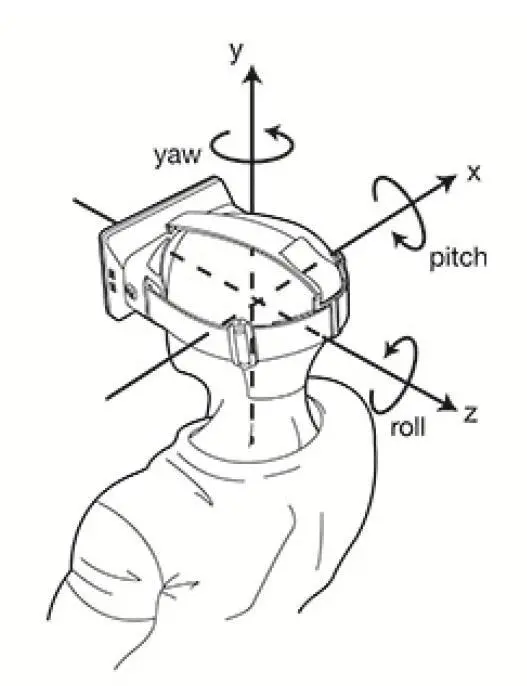

注意：修改虚幻编辑器中的位置和朝向并不能改变`To Video Display`模块中的显示效果。

### **选择场景**

测试基准模型所需的场景和路网由该子系统的以下部分指定：

- [Simulation 3D Scene Configuration](https://ww2.mathworks.cn/help/driving/ref/simulation3dsceneconfiguration.html) 模块的场景名称参数 `Scene name `设置为 [US City Block](https://ww2.mathworks.cn/help/vdynblks/ref/uscityblock.html)。 该城市街区道路网络由十五个单向交叉口组成，每个交叉口有两个红绿灯。 本例使用美国城市街区场景的一部分来测试模型。

- [Scenario Reader](https://ww2.mathworks.cn/help/driving/ref/scenarioreader.html?s_tid=doc_ta) 模块将智能车信息作为输入并执行闭环模拟。 此块从基础工作区读取 `drivingScenario` 对象场景。 该场景包含所需的道路网络。路网与美国城市街区场景的一部分紧密匹配，并包含一个十字路口。

您可以使用 `helperDisplayTrafficLightScene` 函数显示城市街区场景的选定部分。指定 `x` 和 `y` 限制以选择所需的场景区域并绘制提取的场景。

xlimit = [-110 70];
ylimit = [-105 105];
hFigure = helperDisplayTrafficLightScene(xlimit, ylimit);
snapnow;
close(figure);

`helperGetTrafficLightScenario` 函数指定当车道信息不可用时，本车要遵循的参考路径。 **Reference Path Info** 模块读取存储在基础工作区变量`referencePathInfo` 中的引用路径。 智能车可以根据参考轨迹在交叉路口直行或左转。 可以通过设置 `helperGetTrafficLightScenario` 函数的输入值来选择这些参考轨迹之一。 将值设置为

- `直行` - 使智能车自我车辆直接通过十字路口。

- `左转` - 使智能车在十字路口左转。

**Set Velocity** 模块从基本工作区变量 `setVelocity` 读取速度值，并将其作为输入提供给控制器。

### **设置车辆位置**

该场景包含一辆智能车和两辆非智能车。 场景中每辆车的位置由子系统的这些部分指定：

- [Simulation 3D Vehicle with Ground Following](https://ww2.mathworks.cn/help/driving/ref/simulation3dvehiclewithgroundfollowing.html) 模块提供了一个可以改变车辆在 3D 场景中的位置和方向接口。

- **Ego** 输入端口控制智能车的位置，该位置由 `Simulation` `3D` `Vehicle` `with` `Ground` `Following` 模块指定。 `Simulation 3D Vehicle with Ground Follow` 模块的 `ActorName `掩码参数指定为 `EgoVehicle`。

- [Cuboid To 3D Simulation](https://ww2.mathworks.cn/help/driving/ref/cuboidto3dsimulation.html) 模块将智能车姿态坐标系（相对于车辆后轴中心下方）转换为 3D 模拟坐标系（相对于车辆中心下方）。

- [Scenario Reader](https://ww2.mathworks.cn/help/driving/ref/scenarioreader.html) 模块还输出目标车辆在智能车坐标中的车道和动作者姿势的真实信息。 此示例中有两个目标车辆，由另一个具有`Ground Following` 模块的 `Simulation 3D Vehicle` 指定。

- [Vehicle To World](https://ww2.mathworks.cn/help/driving/ref/vehicletoworld.html) 模块将动作者姿势坐标从自我车辆坐标转换为世界坐标。

**跟踪和传感器融合**子系统融合了[**驾驶雷达数据产生器**](https://ww2.mathworks.cn/help/driving/ref/drivingradardatagenerator.html)和[**视觉检测产生器**](https://ww2.mathworks.cn/help/driving/ref/visiondetectiongenerator.html)模块生成的智能车周围的车辆检测结果，并使用[**多目标跟踪**](https://ww2.mathworks.cn/help/driving/ref/multiobjecttracker.html)模块跟踪融合的检测结果。视觉检测生成器模块还提供关于本车的车道检测，有助于识别存在于本车车道中的车辆。

## 车辆检测

参考[使用前景检测跟踪车辆](https://ww2.mathworks.cn/help/vision/ug/tracking-cars-using-foreground-detection.html)，说明如何使用**高斯混合模型** (GMM) 检测和计算视频序列中的汽车。**检测**和**车辆计数**可用于分析交通模式。检测也是执行更复杂任务（例如按类型跟踪或分类车辆）之前的第一步。

这里使用 `vision.ForegroundDetector `来估计从**固定相机**捕获的视频序列的前景像素。使用高斯混合模型估计`vision.ForegroundDetector `背景并生成突出前景对象（这里指移动车辆）的前景蒙版。

然后使用 Blob Analysis 模块分析前景蒙版，生成汽车周围的边界框。最后，将汽车数量和边界框绘制到原始视频中以显示最终结果。

### 使用高斯混合模型进行前景检测

将彩色或灰度视频帧与背景模型进行比较，以确定各个像素是背景还是前景的一部分。然后它计算前景掩码。通过使用背景减除，您可以检测从固定相机拍摄的图像中的前景对象。

% 参考: demo\Examples\R2022b\vision\viptrafficExample\viptraffic.slx

addpath(fullfile(matlabroot, 'toolbox', 'driving', 'drivingdemos'));

## 在仿真场景中控制交通灯

该模型使用 **Simulation 3D Traffic Light Controller** 辅助模块来配置和控制虚幻场景中的交通灯状态。 **Simulation 3D Traffic Light Controller** 辅助模块通过使用基于定时器或基于状态的模式来控制交通灯的状态。 可以使用控制模式掩码参数选择所需的模式。 默认情况下，此模型使用基于状态的模式。 有关基于定时器模式的信息，请参见模块掩码说明。

在基于状态的模式下，模块会覆盖由交通灯 ID 输入端口指定的交通灯状态。 交通灯 ID 输入端口的值由 `helperGetTrafficLightScenario` 函数中的` intersectionInfo.trafficLightToNegotiate` 变量设置。 在此模型中，交通灯 ID 输入端口的值设置为 16。这意味着该模块控制美国城市街区场景中 ID 值为 16 的交通灯。 美国城市街区场景中存在的所有交通灯的状态由 `Simulation 3D Traffic Light Controller `帮助模块的 `Ground Truth` 输出端口返回。 该模型使用真实信息测试决策逻辑和控制，不需要基于感知的交通信号灯检测。

**交通灯选择** 模块从 `Ground Truth `输出中提取 ID 值为 16 的交通灯状态。 **交通灯决策逻辑**参考模型使用状态值在前车和红绿灯之间进行仲裁。 有关**交通灯决策逻辑**参考模型的更多信息，请参阅[交通灯协商](https://ww2.mathworks.cn/help/driving/ug/traffic-light-negotiation.html)的示例。

**交通灯停止线位置** 模块提供与所选交通灯 `trafficLightToNegotiate `对应的交叉口处的停止线位置。 停止线位置值由`intersectionInfo.tlStopLinePosition` 指定。

**Intersection Center** 模块提供场景中路网的交叉点中心的位置。 这是使用来自 `helperGetTrafficLightScenario `的输出 `intersectionInfo `获得的。

当 `智能车` 靠近交通灯并且交通灯改变其状态时，测试决策逻辑和控制通常很重要。 本示例中使用的模型使交通信号灯能够在 `智能车` 靠近交通信号灯时改变状态。

`交通灯停止线距离` 模块计算所选交通灯 trafficLightToNegotiate 的停止线与当前智能车位置之间的欧氏距离。

**交通灯决策逻辑**使用距离值来决定最重要的目标 (Most Important Object, MIO)，即智能车前方最近的物体。 它可以是本车道上的领头车辆或交通灯。

**交通灯切换逻辑**模块输出 `tlState`，即需要设置的交通灯状态。 这是使用 Stateflow® 实现的，并在 `智能车` 比指定距离更靠近交通灯时使用距离值触发状态更改。

打开**交通灯切换逻辑**模块。

% open_system("TLNWithUnrealTestBench/Sensors and Environment/Traffic Light Switching Logic", 'force');

**交通灯切换逻辑**使用 `Configuration params` 掩码参数从基础工作空间读取交通灯配置 `trafficLightConfig`。 可以使用 `trafficLightConfig` 结构来配置不同的测试场景。 该结构在测试场景函数中定义，具有以下字段：`stateChangeDistance`、`initialState` 和 `changeState`。

- `initialState` 在状态改变之前指定交通灯的状态。

- `stateChangeDistance` 指定 `智能车` 到交通信号灯的阈值距离，在该距离处应该发生状态变化。

- `changeState` 指定状态更改后要设置的交通灯状态。 

状态切换基于设置的配置以及当 `智能车` 到达 stateChangeDistance 时发生。 当 `initialState` 为红色且 `changeState` 为绿色时，Stateflow 图从红色状态切换到绿色状态。 相反，当 `initialState` 为 Green 且 `changeState` 为 Red 时，Stateflow 图被建模，状态转换发生在从 Green 状态到 Yellow 状态，一秒钟后，交通灯切换到 Red 状态。

### 绿灯变红灯时的车辆行为仿真

本节测试当智能车距离交通灯很近并且交通灯状态从绿色变为红色时的决策逻辑。 在此测试场景中，领头车辆在本车道行驶并穿过十字路口。 交通信号灯状态为前车保持绿色，当本车距离停止线 10 米时变为红色。 预计智能车将跟随领头车辆，协商状态转换，并在停止线前完全停下来。

配置 TLNWithUnrealTestBench 模型以使用 scenario_03_TLN_straight_greenToRed_with_lead_vehicle 测试场景。

helperSLTrafficLightNegotiationWithUnrealSetup(...
    "scenario_03_TLN_straight_greenToRed_with_lead_vehicle");

显示测试场景设置的 `trafficLightConfig` 结构参数。

disp(trafficLightConfig');

仿真模型。 在仿真过程中，模型将仿真后分析所需的信号记录到 `logsout` 中。

为了减少命令窗口输出，先关闭 MPC 更新消息。

% cc;  % change  to current directory to solve the problem: Undefined function or variable 'cmap'. (sim3dColormap.m)
mpcverbosity('off');
% 在运行前需要先从Simulink模块中打开虚幻编辑器（记得关闭Simulink模块，否则出现错误：有未应用的更改。请在运行仿真之前应用或取消这些更改）
path = fullfile(buf_dir, 'AutoVrtlEnv', 'AutoVrtlEnv.uproject');
editor = sim3d.Editor(path);
open(editor);  % 需要在每次仿真完关闭当前打开的虚幻编辑器

sim("TLNWithUnrealTestBench");
% 运行后等待出现"In Unreal Editor, select 'Play' to view the scene"再在虚幻编辑器中点击运行
% 如果在虚幻编辑器点击运行后在matlab中出现"read error"的错误，则重启电脑可以解决（原因不明，可能是运行其他的造成端口堵塞）

使用 `helperPlotTrafficLightControlAndNegotiationResults` 函数绘制模拟结果。

hFigResults = helperPlotTrafficLightControlAndNegotiationResults(logsout, trafficLightConfig.stateChangeDistance);

检查结果。

- **交通灯状态**图显示交通灯的状态。 **到交通灯停止线距离**图显示本车与交通灯对应的停止线之间的距离。 可以看到交通灯的初始状态为绿色，并且随着智能车接近停止线，状态从绿色变为黄色。 当自我车辆距离停止线 10 米时，状态从黄色变为红色。

- **相对纵向距离**图显示了智能车与最重要目标 (MIO) 之间的相对距离。 MIO 是智能车前方最近的物体。 它可以是智能车道上的领头车辆或红绿灯。 当交通灯状态为绿色时，智能车跟随领头车辆并保持安全距离。 当交通信号灯从绿色变为红色时，智能车与前车之间的距离会减小。 这是因为，当智能车辆接近停止线时，红绿灯被检测为 MIO。 此时，交通灯状态为红色或黄色。

- **智能车加速度**图显示**车道跟随控制器**的加速度曲线。 请注意，这紧随相对距离的下降，以响应将红色交通灯检测为 MIO。

- **智能车速度**图显示了智能车辆的速度曲线。 请注意，智能车速度因黄色和红色交通灯的反应而减慢，并在停止线之前完全停止。 当速度为零时，可以通过将绘图与**离交通灯停止线的距离**进行比较来验证这一点。

可以参考[交通灯协商](https://ww2.mathworks.cn/help/driving/ug/traffic-light-negotiation.html)示例以了解有关此分析以及决策逻辑与控制器之间交互的更多信息。

关闭图。

close(hFigResults);

### 红灯变绿灯时的车辆行为仿真

本节测试当智能车辆距离交通灯很近并且交通灯状态从红色变为绿色时的决策逻辑。 此外，当智能车辆的交通灯为绿色时，交叉路口车辆处于十字路口。 智能车辆的交通灯状态最初为红色，当智能车辆距离停止线 11 米时变为绿色。当状态为红色时，智能车辆在接近交通信号灯时预计会减速，并且当交通信号灯状态从红色变为绿色时必须开始加速。 在加速继续行驶之前，还需要等待交叉路口的车辆通过十字路口。

测试场景函数 `scenario_04_TLN_straight_redToGreen_with_cross_vehicle `实现了这个场景。 配置 `TLNWithUnrealTestBench` 模型以使用此场景。

helperSLTrafficLightNegotiationWithUnrealSetup(...
    "scenario_04_TLN_straight_redToGreen_with_cross_vehicle");

显示为此测试场景设置的 `trafficLightConfig` 结构参数。

disp(trafficLightConfig');

仿真模型。

sim("TLNWithUnrealTestBench");

绘制仿真结果。

hFigResults = helperPlotTrafficLightControlAndNegotiationResults(logsout, trafficLightConfig.stateChangeDistance);

检查结果。

- **交通灯状态**图显示初始交通灯状态为红色。 当自我车辆距离停止线 11 米时，交通灯状态从红色变为绿色。

- 由于没有领先车辆，因此**相对纵向距离**图与**到交通灯停止线的距离**图非常接近。 注意检测到交叉车辆时相对距离的突然下降。

- 智能车加速度图显示，智能车辆在看到红色交通灯时试图减速。 但是，为了响应状态变为绿色，您可以观察到加速度增加。 然后，您可以注意到一个硬制动配置文件以响应十字路口的交叉路口车辆。

- **智能车速度**图紧跟**智能车加速度**图，并显示随着**智能车**接近交叉路口速度下降。 还可以注意到响应绿色交通灯的速度略有增加，随后响应交叉交通车辆的速度降低。

关闭图。

close(hFigResults);

### 探索其他场景

在前面的部分中，探索了 `scenario_03_TLN_straight_greenToRed_with_lead_vehicle` 和 `scenario_04_TLN_straight_redToGreen_with_cross_vehicle` 场景的系统行为。 下面是与 `TLNWithUnrealTestBench` 兼容的场景列表。

使用这些额外的场景来分析不同条件下的 `TLNWithUnrealTestBench`。

启用 MPC 更新消息。

mpcverbosity('on');
% close(editor);

您可以使用本示例中的建模模式来构建您自己的交通灯协商应用程序。